## **Figure 4c**

**Run Time: **Seconds.

**Requirements: **thresholdfun.m, parameters.m all need to be in the working directory so that this script can call them

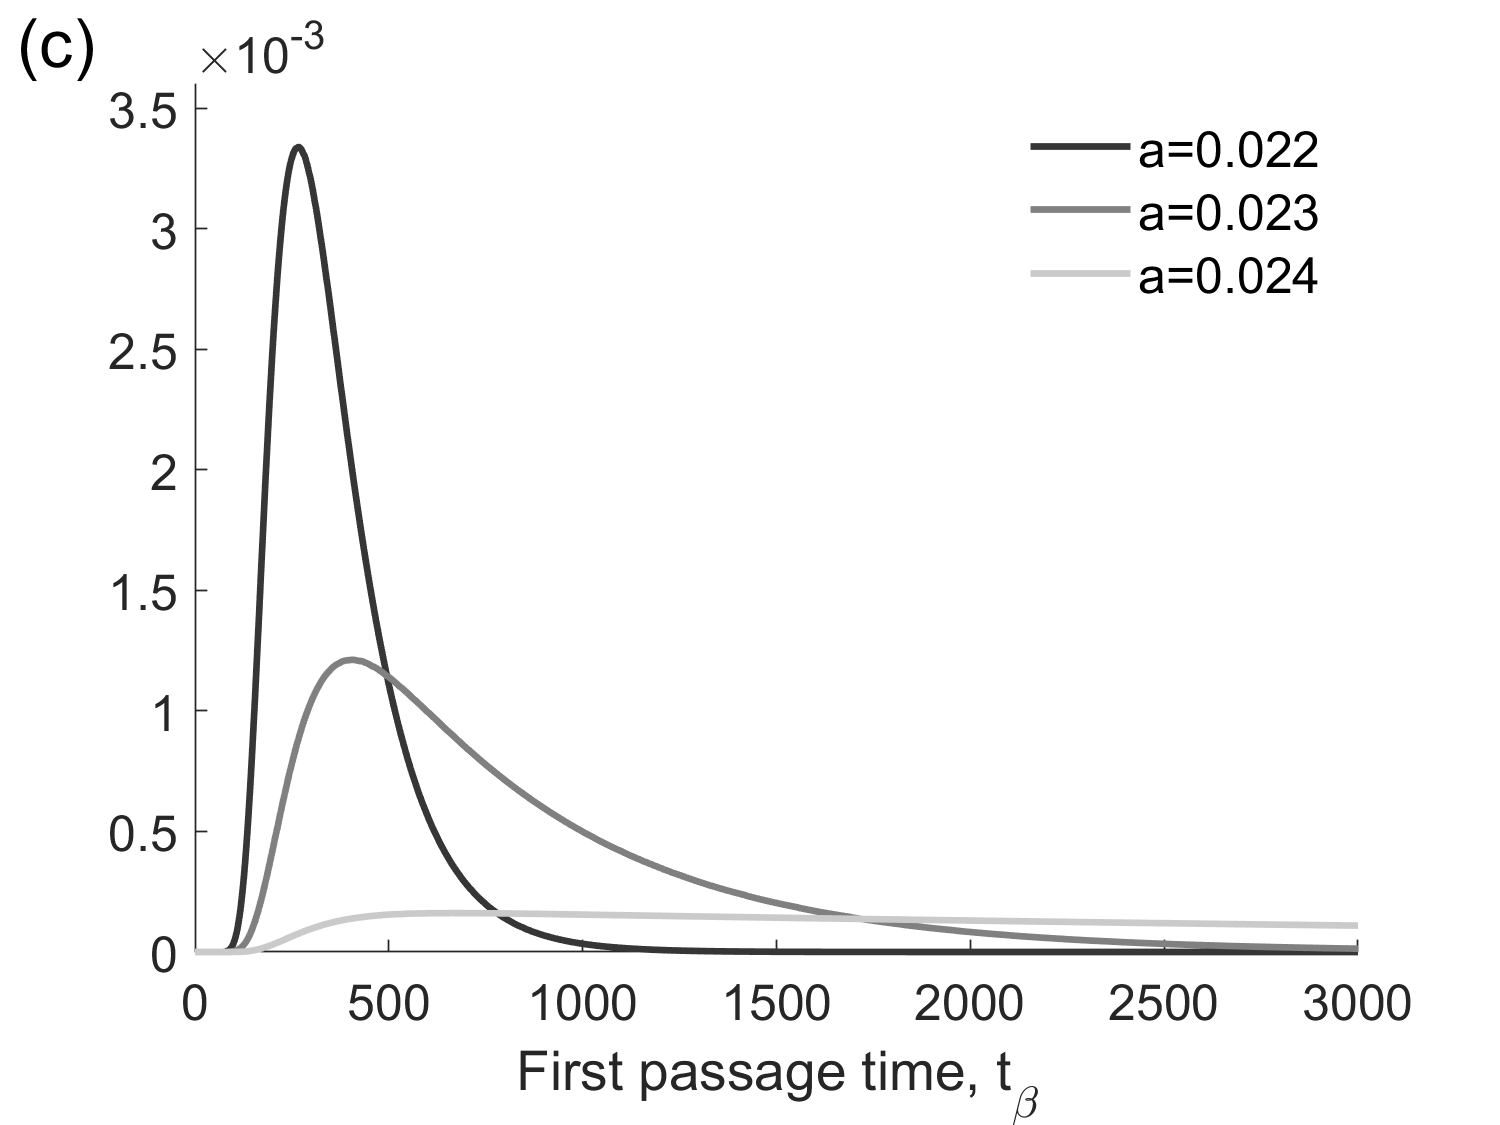

clear;
xinit = 0.3; % initial value of interest
global a
avals = [0.022, 0.023, 0.024]; 

% custom colors
% Define the two RGB endpoint colors
color1 = (1/255)*[54, 54, 54]; % dark gray
color2 = (1/255)*[128, 128, 128]; % medium gray
color3 = (1/255)*[202, 202, 202]; % light gray
col = [color1; color2; color3];

%Define space & time domains
[r,K,h,q,sigma] = parameters();
t = linspace(0,3000,2000);

figure
hold on
for j=1:3
    a=(avals(j));
    beta = thresholdfun(a);
    x0 = linspace(0.1,beta,2000);
    % Calculate the absolute differences
    abs_diff = abs(x0 - xinit);

    % Find the index of the minimum absolute difference
    [min_diff, index] = min(abs_diff);

    % Get the nearest element from vector x
    nearest_element = x0(index);

    %Solve the pde
    sol = pdepe(0,@eqn,@ic,@bc,x0,t);

    %Retrieve the Reliability Function as the appropriate column in sol
    reliability = sol(:,index);

    %Calculate the pdf (gradient should take a numerical time derivative)
    pdf = -gradient(reliability,t);
    
    % Plot pdf 
    plot(t,pdf,'color',col(j,:),'LineWidth',2);
end

% Plot details
legend('a=0.022','a=0.023','a=0.024',"FontSize",15,'Location', 'Northeast', 'Box', 'off');

xlabel('First passage time, t_{\beta}',"FontSize",20);
xlim([0 max(t)])
ylim([0 0.0036])
ax = gca;
ax.FontSize = 15;
hold off
% 
% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size
annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(c)', 'FontSize', 20, 'EdgeColor', 'none');
exportgraphics(gcf, 'Fig4c.pdf', 'BackgroundColor', 'none');

**Notes on Functions: **eqn is the PDE, u0 is the initial condition function, and bc is the Boundary Condition Functions

function [c,f,s] = eqn(x0,t,P,DPDx0)

%Parameters
global a
[r,K,h,q,sigma] = parameters();

%Time Derivative is Not Scaled
c = 1;

%Diffusion Vector Transformed for BK
f = DPDx0*(.5*sigma^(2)*x0^(2));

%Drift Vector Transformed for BK
s = (r*x0*(1-(x0/K)) - (a*x0^(q))/(x0^(q) + h^(q)) - (sigma^(2) * x0))*DPDx0;

end

function u0 = ic(x0)

%The probability we're in target region at t = 0 is 1 
%Independent of the x0
u0 = 1;

end


function [pl,ql,pr,qr] = bc(x0l,Pl,x0r,Pr,t)

%Probability of Being in Target Space if we Start @ 0 for any time is 1
%given 0 should act like a steady state
pl = 1-Pl;
ql = 0;

%Probability of Being in Target Space if we Start @ mu = 0
pr = Pr;
qr = 0;
end










